## 迭代格林函数方法

clear;
energyscale = 4;
N_point = 401;
Width = 50;
t = 1;
Ec = 0;
epsilon_0 = Ec;
eta = 1e-8;

U = 0;
omega = linspace(-energyscale,energyscale,N_point);

Accuracy = 1e-15;
%% 导线哈密顿量
H00 = epsilon_0 * eye(Width) - t' * diag(ones(Width-1,1),-1) - t * diag(ones(Width-1,1),+1);
V = -t * eye(Width);
Iden = eye(Width);
Tr = 0.5;

%% 计算格林函数与电导率
% 中心区哈密顿量
epsilon_c = epsilon_0 + U;
HCC = epsilon_c * eye(Width) - t' * diag(ones(Width-1,1),-1) - t * diag(ones(Width-1,1),+1);
layer = 101;
Transmission_RGF = zeros(1,length(omega));
tstart = tic;
for ii = 1:length(omega)
    G_00_Right = SurfaceGreenFunction_V2_mex(H00, V, omega(ii), Accuracy);
    G_00_Left = SurfaceGreenFunction_V2_mex(H00, V', omega(ii), Accuracy);

    Sigma_L = SurfaceGreenFunction_SelfEnergy(G_00_Left, Tr*V');
    Sigma_R = SurfaceGreenFunction_SelfEnergy(G_00_Right, Tr*V);

    Gamma_L = SurfaceGreenFunction_Broadening(Sigma_L);
    Gamma_R = SurfaceGreenFunction_Broadening(Sigma_R);


    G_Centre_Ret = SurfaceGreenFunction_Gcc_1L(HCC, V, layer, omega(ii), Sigma_L, Sigma_R);
    Transmission_RGF(ii) = real(GreenFunction_Transmission(Gamma_L, Gamma_R, G_Centre_Ret));
end
figure(1)
subplot(1,2,2)
% plot(Transmission, omega)
plot(Transmission_RGF, omega)
Ylim = ylim;
hold on
ylabel('Energy')
xlabel('Transmissioin')
tfin = toc(tstart);
fprintf('RGF直接计算耗时 %4.4f second\n', tfin)

RGF直接计算耗时 7.9563 second


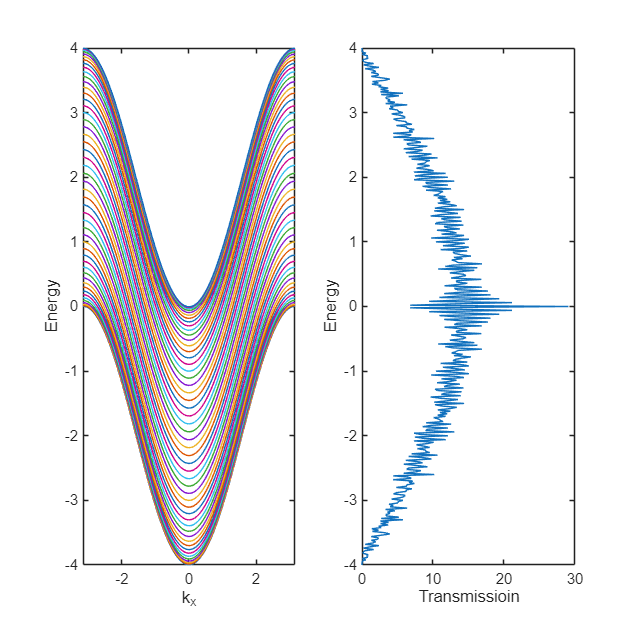



%% Test example Energy band of periodic model
kx = linspace(-pi,pi,N_point);
energy_band = zeros(Width, length(kx));
% 中心区哈密顿量，测试用例导线模型
for ii = 1: length(kx)
    Hk = H00 + V * exp(1i*kx(ii)) + V' * exp(-1i*kx(ii));
    energy_band(:,ii) = eig(Hk);
end
subplot(1,2,1)
plot(kx, energy_band);
xlabel('k_x','Interpreter','tex')
ylabel('Energy')
xlim([-pi,pi])
ylim(Ylim);

## 三对角矩阵求逆方法

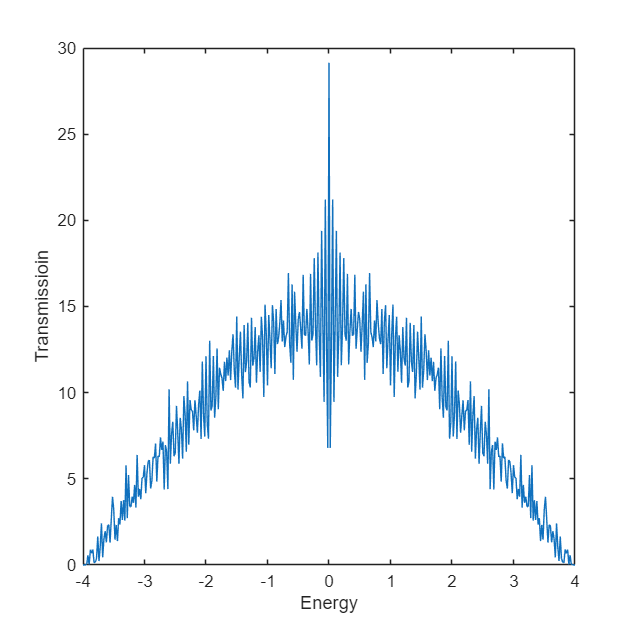


%% 计算格林函数与电导率
% 中心区哈密顿量
tstart = tic;
epsilon_c = epsilon_0 + U;
HCC = epsilon_c * eye(Width) - t' * diag(ones(Width-1,1),-1) - t * diag(ones(Width-1,1),+1);

HCC_preInv = reshape(repmat(HCC, 1, layer), Width, Width, layer);
V_preInv = reshape(repmat(V, 1, layer - 1), Width, Width, layer-1);

Transmission_inv = zeros(1,length(omega));
for ii = 1:length(omega)
    [G_00_Right,Count] = SurfaceGreenFunction_V2_mex(H00, V, omega(ii), Accuracy);
    G_00_Left = SurfaceGreenFunction_V2_mex(H00, V', omega(ii), Accuracy);

    Sigma_L = SurfaceGreenFunction_SelfEnergy(G_00_Left, Tr*V');
    Sigma_R = SurfaceGreenFunction_SelfEnergy(G_00_Right, Tr*V);

    temp_H = (omega(ii)+1i*eta)*eye(Width) - HCC_preInv;
    temp_H(:, :, 1) = temp_H(:, :, 1) - Sigma_L;
    temp_H(:, :, layer) = temp_H(:, :, layer) - Sigma_R;

    Gamma_L = SurfaceGreenFunction_Broadening(Sigma_L);
    Gamma_R = SurfaceGreenFunction_Broadening(Sigma_R);
    
    % G_Centre_Ret = tridiag_block_inv(temp_H, V_preInv, 1, layer);
    G_Centre_Ret = tridiag_block_inv_mex(temp_H, V_preInv, int64(1), int64(layer));
    Transmission_inv(ii) = real(GreenFunction_Transmission(Gamma_L, Gamma_R, G_Centre_Ret));
end
figure
plot(omega, Transmission_inv)
xlabel('Energy')
ylabel('Transmissioin')

tfin = toc(tstart);
fprintf('三对角矩阵求逆耗时 %4.4f second\n', tfin)

三对角矩阵求逆耗时 14.0821 second
